## VISUALIZACIÓN DE DISTINTOS CÍRCULOS EN EL DOMINIO DE FOURIER

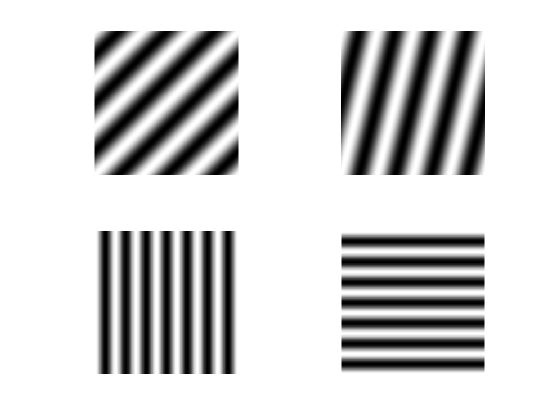

circ1 = fourier_circle(4,4,1);
circ2 = fourier_circle(2,5,1);
circ3 = fourier_circle(1,8,1);
circ4 = fourier_circle(8,1,1);

subplot(2,2,1);
imshow(circ1, []);
subplot(2,2,2);
imshow(circ2, []);
subplot(2,2,3);
imshow(circ3, []);
subplot(2,2,4);
imshow(circ4, []);

Como podemos observar, cuando tenemos círculos de radio 1, la posición de los puntos nos marca el número de bandas en vertical y horizontal que obtendremos en la imagen al devolver dicha informacion al dominio de las imágenes.

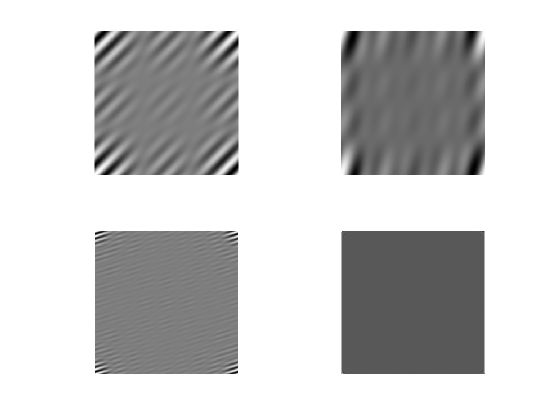

circ1 = fourier_circle(8,8,2);
circ2 = fourier_circle(2,6,3);
circ3 = fourier_circle(30,10,5);
circ4 = fourier_circle(70,70,60);

subplot(2,2,1);
imshow(circ1, []);
subplot(2,2,2);
imshow(circ2, []);
subplot(2,2,3);
imshow(circ3, []);
subplot(2,2,4);
imshow(circ4, []);

Aumentar el tamaño del radio produce que las bandas empiecen a desdibujarse, ya que las frecuencias comienzan a verse solapadas. Como podemos observar en estas imágenes, para radio 2 se pueden apreciar aún las banda más o menos correctamente. Para radio 3 la superposición es mucho mayor, para radio 5 apenas se pueden apreciar las bandas en los bordes (luego están demasiado solapadas), y para radio 60, la imagen a simple vista ya parece completamente homogénea a nuestro ojo

## Reducción de ruido en el dominio de Fourier

Mostramos en primer lugar la imagen original junto con su transformada en el dominio de Fourier

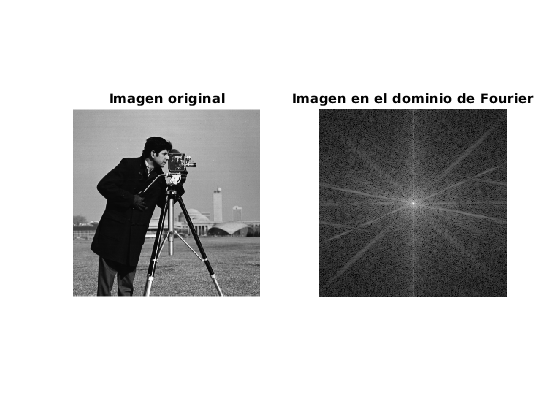

cameraman = imread("cameraman.png");
cameraman = im2double(cameraman);

ft = fft2(cameraman);
ft_shift = fftshift(ft);

flog = log(1+abs(ft_shift));
subplot(1,2,1);
imshow(cameraman);
title("Imagen original")
subplot(1,2,2);
imshow(flog, []);
title("Imagen en el dominio de Fourier")

A continuación, mostramos la imagen junto con su transformada tras haber añadido ruido gaussiano

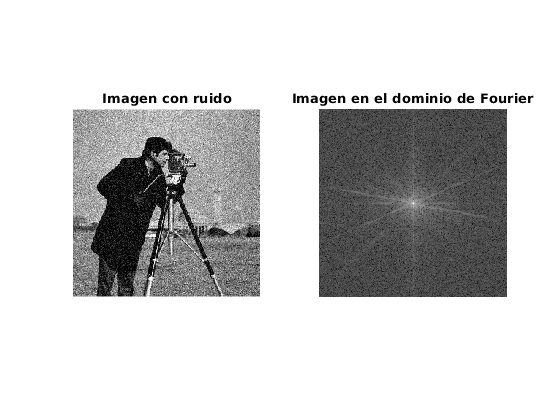

cameraman_noisy = imnoise(cameraman, 'gaussian');

ft = fft2(cameraman_noisy);
ft_shift = fftshift(ft);

map = colormap(gray(256));

flog = log(1+abs(ft_shift));
subplot(1,2,1);
imshow(cameraman_noisy);
title("Imagen con ruido")
subplot(1,2,2);
imshow(flog, []);
title("Imagen en el dominio de Fourier")

Como podemos observar, las frecuencias que han aparecido al introducir ruido son frecuencias altas, por lo que serán las que tengamos que eliminar. Utilizaremos por tanto un filtro paso bajo de tipo gaussiano. En función de la sigma que utilicemos, eliminaremos más ruido, pero a cambio de perder definición de la imagen

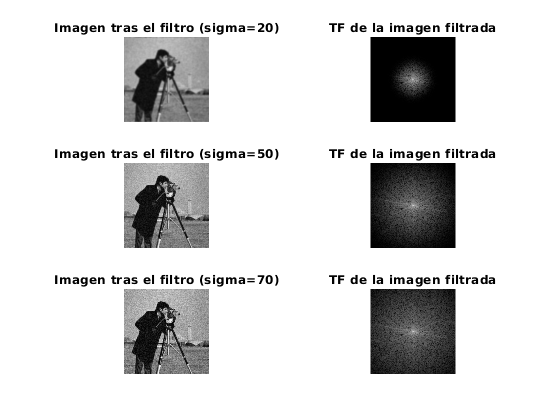

mi=size(cameraman_noisy, 1)/2;
mj=size(cameraman_noisy, 2)/2;
x=1:size(cameraman_noisy, 2);
y=1:size(cameraman_noisy, 1);
[Y, X]=meshgrid(y-mi, x-mj);
dist = hypot(X, Y);

ft = fft2(cameraman_noisy);

sigma=20;
H_gau=exp(-(dist.^2)/(2*(sigma^2))); %gaussiana
ft_filtered_20 = fftshift(H_gau).*ft;
cameraman_unnoise_20 = real(ifft2(ft_filtered_20));

sigma=50;
H_gau=exp(-(dist.^2)/(2*(sigma^2))); %gaussiana
ft_filtered_50 = fftshift(H_gau).*ft;
cameraman_unnoise_50 = real(ifft2(ft_filtered_50));

sigma=70;
H_gau=exp(-(dist.^2)/(2*(sigma^2))); %gaussiana
ft_filtered_70 = fftshift(H_gau).*ft;
cameraman_unnoise_70 = real(ifft2(ft_filtered_70));

subplot(3,2,1);
imshow(cameraman_unnoise_20);
title("Imagen tras el filtro (sigma=20)")
subplot(3,2,2);
imshow(log(1+abs(fftshift(ft_filtered_20))),[]);
title('TF de la imagen filtrada');
subplot(3,2,3);
imshow(cameraman_unnoise_50);
title("Imagen tras el filtro (sigma=50)")
subplot(3,2,4);
imshow(log(1+abs(fftshift(ft_filtered_50))),[]);
title('TF de la imagen filtrada');
subplot(3,2,5);
imshow(cameraman_unnoise_70);
title("Imagen tras el filtro (sigma=70)")
subplot(3,2,6);
imshow(log(1+abs(fftshift(ft_filtered_70))),[]);
title('TF de la imagen filtrada');

## Descomposición de imagen usando Wavelet y distribución de coeficientes

En primer lugar, calculamos la transformada Wavelet de la imagen utilizando las funciones Bior3.7 a tres niveles:

barbara = im2double(imread("barbara.png"));
n = 3;                   % Nivel de descomposición
w = 'bior3.7';              % Tipo de wavelet
[C, S] = wavedec2(barbara, n, w);

Una vez hemos realizado dicho cálculo, podemos mostrar la distribución acumulada de los valores absolutos de los coeficientes calculados:

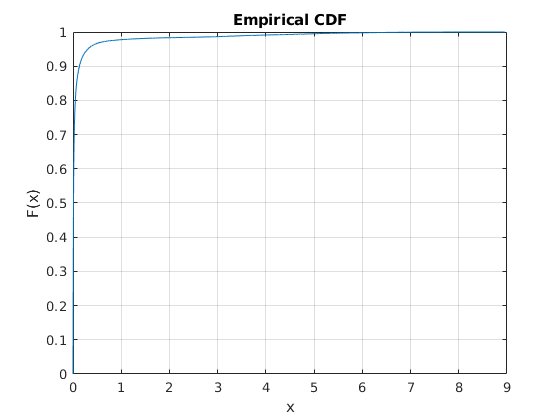

subplot(1,1,1);
cdfplot(abs(C));

Como podemos observar en el gráfico, el 90 % de los coeficientes son inferiores a 0.13, y más del 97% de los mismos son inferiores a 1

## Compresión de la imagen anulando los coeficientes menores

Ahora, podemos utilizar la información anterior para comprimir la imagen. Para quedarnos sólo con el 10 % de los coeficientes, tenemos que situar el threshold en 0.1345 (hemos comprobado en la gráfica anterior que en dicho punto está el corte). La función wdencmp hace 0 todos los coeficientes cuyo valor absoluto sea menor que el threshold en cuestión. Como podemos observar, en la imagen de pequeño tamaño, ni siquiera se aprecia diferencia entre las imágenes (puede abrirse la figura en una nueva ventana haciendo click en la flecha que aparece en la esquina superior derecha al deslizar el ratón por encima de la imagen). Cuando se ve la imagen en grande sí se pueden apreciar ciertos cambios, como la falta de definición en las listas del velo de la cabeza.

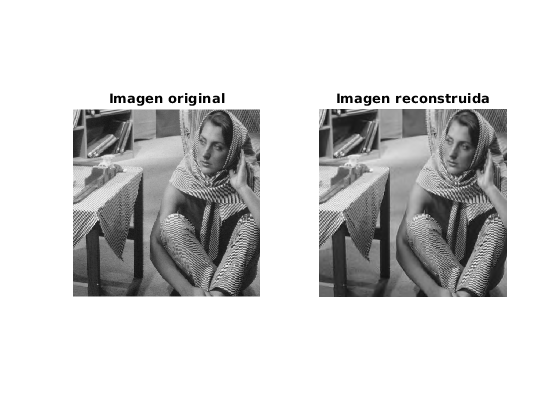

opt = 'gbl'; % Global threshold
thr = 0.1345;    % Threshold
sorh = 'h';  % Hard thresholding
keepapp = 1; % Approximation coefficients cannot be thresholded
[xd,~,~,~,~] = wdencmp(opt,C,S,w,n,thr,sorh,keepapp);
subplot(1,2,1);
imshow(barbara);
title("Imagen original");
subplot(1,2,2);
imshow(xd);
title("Imagen reconstruida");

Si aumentamos el threshold, más coeficientes se anulan, y por tanto la imagen está más comprimida, a cambio de una pérdida de calidad. El cambio siguiente sí que se aprecia a simple vista, cuando hemos eliminado todos los coeficientes inferiores a 1. No obstante, estamos hablando de una reducción de tamaño de la imagen de casi el 98 %.

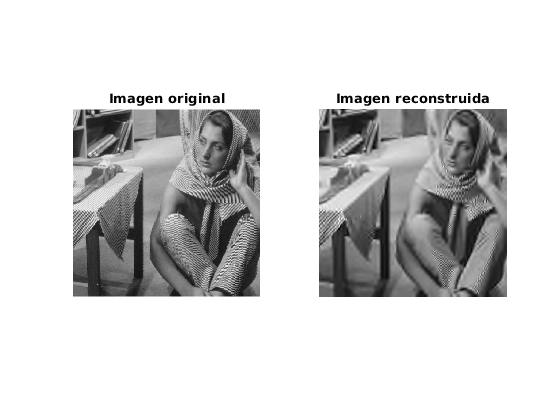

thr = 1;    % Threshold
[xd,~,~,~,~] = wdencmp(opt,C,S,w,n,thr,sorh,keepapp);
subplot(1,2,1);
imshow(barbara);
title("Imagen original");
subplot(1,2,2);
imshow(xd);
title("Imagen reconstruida");

## Estudio del ratio de compresión y el PSNR

En este apartado, vamos a estudiar cómo evoluciona el PSNR en función del ratio de compresión que experimenta la imagen. Para ello, utilizamo la función anterior variando el threshold en pequeña cantidad. Uno de los elementos que devuelve la función anterior es el ratio de compresión de la imagen, y la función psnr nos permite calcular el PSNR entre una imagen y su reconstrucción

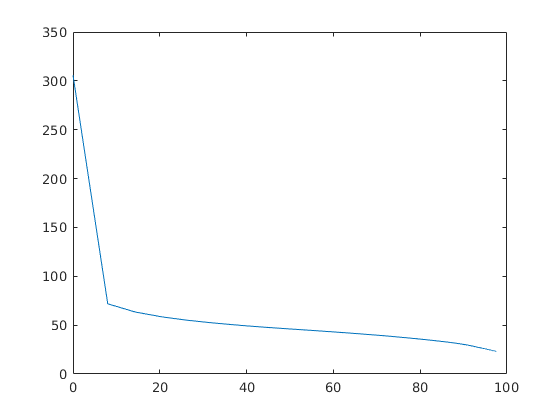

compression_ratios = [];
psnrs = [];
for thr = 0:0.001:1
    [xd,~,~,cr,~] = wdencmp(opt,C,S,w,n,thr,sorh,keepapp);
    compression_ratios = [compression_ratios cr];
    psnrs = [psnrs psnr(xd, barbara)];
end
subplot(1,1,1);
plot(compression_ratios, psnrs);

Como podemos observar, el PSNR decrece muy rápidamente, y luego se estabiliza conforme el nivel de compresión aumenta. No obstante, en todos los casos es relativamente alto. Se considera que la compresión de una imagen es de calidad mientras el PSNR es superior a 30. En nuestro caso, hasta que no estamos cerca de un 90 % de compresión, este valor sigue siendo superior a 30, por lo que podemos conseguir una imagen de relativamente buena calidad almacenando mucha menos información.